Q1

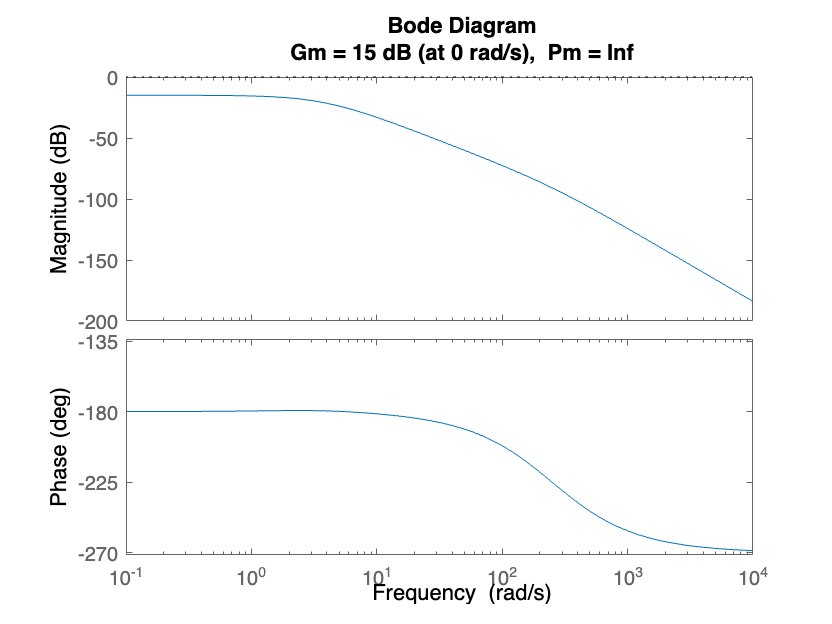

s=tf('s');
G=633/(s^3+250.188*s^2+32.83*s-3542.5);
margin(G)

Q2 

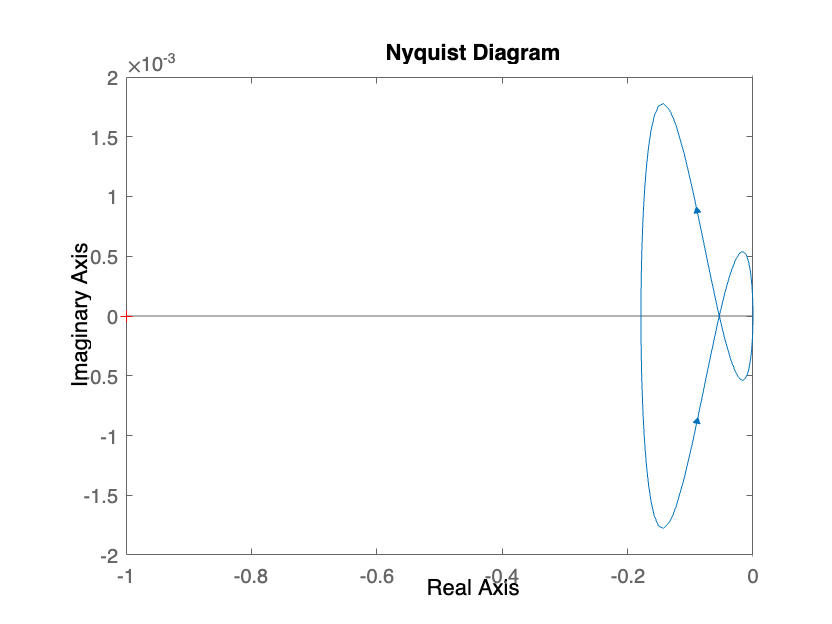

nyquist(G)

zeta = 0.5

zeta = 0.5000

wn = 40

wn = 40

wg=wn*sqrt(-2*zeta^2 + sqrt(1+4*zeta^2))

wg = 38.2458


wpd = 0.62*wg;
Gpd = 1/wpd*s+1

Gpd =
 
  0.04217 s + 1
 
Continuous-time transfer function.



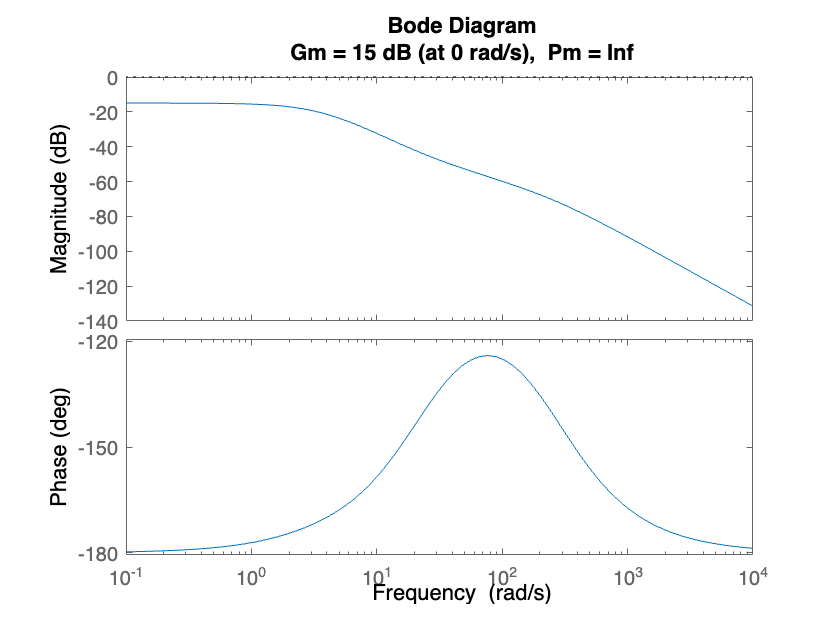

margin(Gpd*G)

kpd = 10^(50.2/20)

kpd = 323.5937

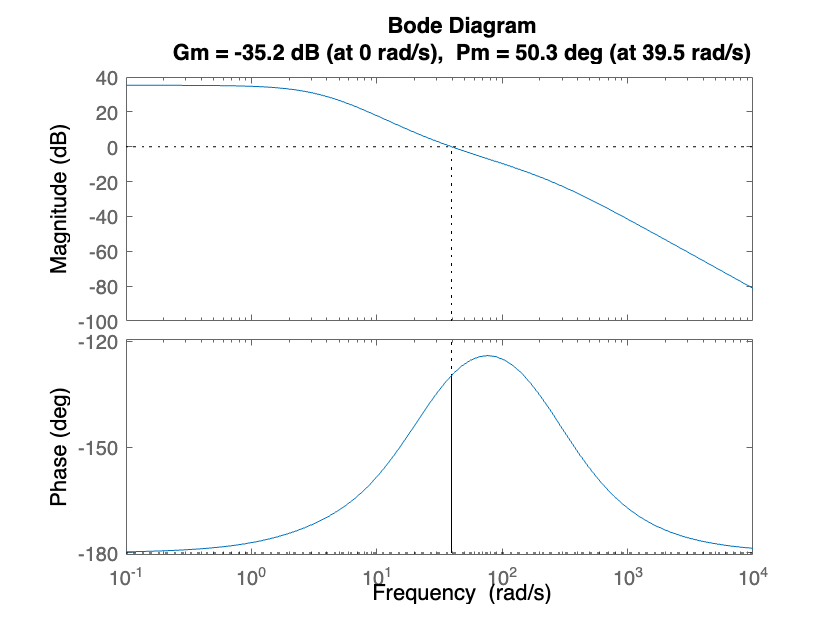

margin(kpd*Gpd*G)


wpi = 0.1*wpd

wpi = 2.3712

Gpi = (s+wpi)/s

Gpi =
 
  s + 2.371
  ---------
      s
 
Continuous-time transfer function.




Gc = kpd*Gpd*Gpi

Gc =
 
  13.65 s^2 + 356 s + 767.3
  -------------------------
              s
 
Continuous-time transfer function.



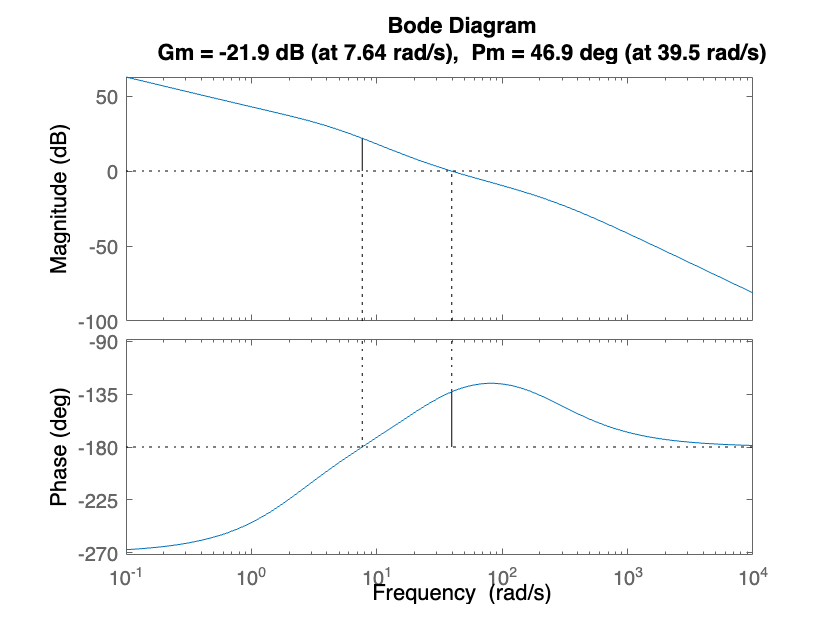

margin(Gc*G)

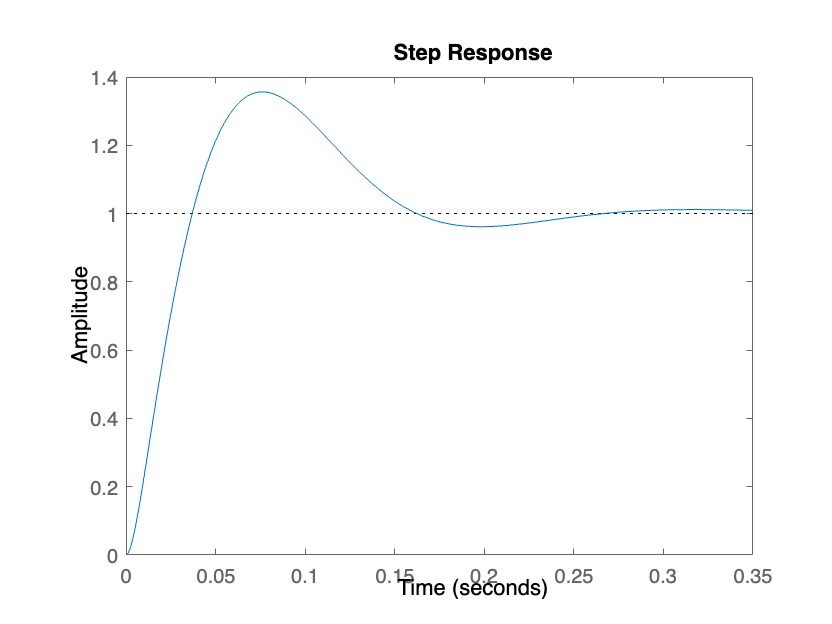

T = feedback(Gc*G,1);
step(T)

stepinfo(T)

ans = struct with fields:
         RiseTime: 0.0266
    TransientTime: 0.2356
     SettlingTime: 0.2356
      SettlingMin: 0.9044
      SettlingMax: 1.3563
        Overshoot: 35.6333
       Undershoot: 0
             Peak: 1.3563
         PeakTime: 0.0760


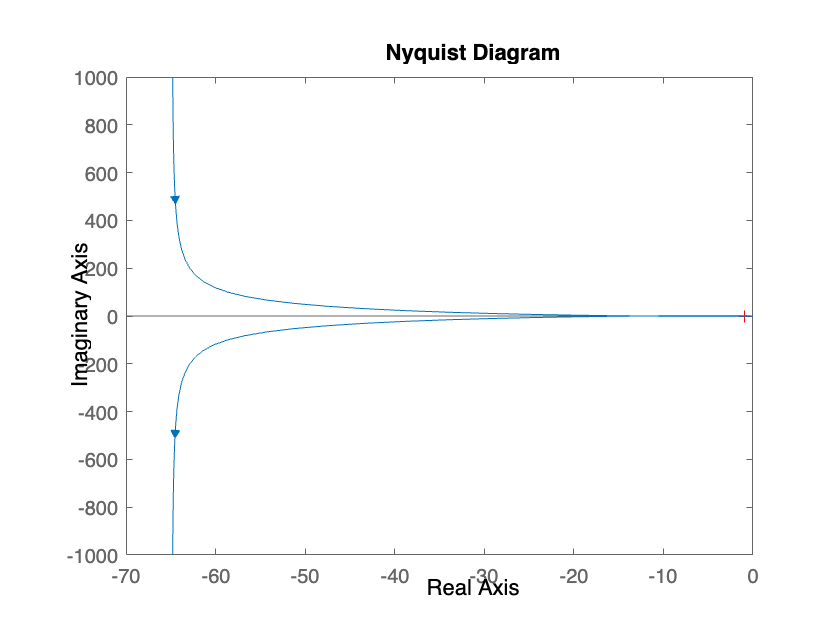

nyquist(kpd*Gpd*Gpi*G)